# HW8

## Problem 1

aE = 149597898;
aJ = 778279959;
mu_S = 132712440017.99;
mu_E = 398600.4415;
mu_J = 126712767.8578;
rE = 6378.1363;
rJ = 71492;

r_parkE = rE+250;
r_parkJ = 2.8*rJ;

aT = 0.5*(aE+aJ);
% from hw7 p2
vp = sqrt(2*mu_S/aE-mu_S/aT) % v+

vp = 38.5772

va = sqrt(2*mu_S/aJ-mu_S/aT) % v-

va = 7.4152


vE = sqrt(mu_S/aE)

vE = 29.7847

vJ = sqrt(mu_S/aJ)

vJ = 13.0583

Earth departure

v_inf_E = vp-vE

v_inf_E = 8.7925

vc_E = sqrt(mu_E/r_parkE)

vc_E = 7.7548

dv_E = sqrt(v_inf_E^2+2*mu_E/r_parkE) - vc_E

dv_E = 6.3016

Jupiter arrival

v_inf_J = vJ-va

v_inf_J = 5.6432

vc_J = sqrt(mu_J/r_parkJ)

vc_J = 25.1595

dv_J = sqrt(v_inf_J+2*mu_J/r_parkJ) - vc_J

dv_J = 10.5006

Total

dv_total = dv_E+dv_J

dv_total = 16.8022

e_parkJ = 0.9

e_parkJ = 0.9000

a_parkJ = r_parkJ/(1-e_parkJ)

a_parkJ = 2.0018e+06

vp_e = sqrt(2*mu_J/r_parkJ-mu_J/a_parkJ)

vp_e = 34.6800

dv_J2 = sqrt(v_inf_J+2*mu_J/r_parkJ) - vp_e

dv_J2 = 0.9801

ah = mu_J/v_inf_J^2

ah = 3.9790e+06

eh = r_parkJ/ah+1

eh = 1.0503

delta = 2*asin(1/eh)

delta = 2.5201

rad2deg(delta)

ans = 144.3894

vn = sqrt(v_inf_J^2+vJ^2-2*v_inf_J*vJ*cos(delta))

vn = 17.9495


gamma_n = asin(v_inf_J/vn*sin(delta))

gamma_n = 0.1841

rad2deg(gamma_n)

ans = 10.5482


rn = aJ;

% rn = 227944135;
% gamma_n = deg2rad(6.05);
% vn = 23.2;

theta_an = atan2((rn*vn^2/mu_S*sin(gamma_n)*cos(gamma_n)),(rn*vn^2/mu_S*cos(gamma_n)^2-1))

theta_an = 0.3905

rad2deg(theta_an)

ans = 22.3727


en = sqrt((rn*vn^2/mu_S-1)^2*cos(gamma_n)^2+sin(gamma_n)^2)

en = 0.8934

pn = rn*(1+en*cos(theta_an))

pn = 1.4212e+09

an = pn/(1-en^2)

an = 7.0386e+09


sqrt(1-(cos(gamma_n)*rn*vn)^2/(mu_S*an))

ans = 0.8934

-mu_S/(2*(vn^2/2-mu_S/rn))

ans = 7.0386e+09

acos((an*(1-en^2)/rn-1)/en)

ans = 0.3905


rp_n = an*(1-en)

rp_n = 7.5064e+08

ra_n = an*(1+en)

ra_n = 1.3327e+10

period_n = 2*pi*sqrt(an^3/mu_S)

period_n = 1.0185e+10

period_n/(3600*24*365)

ans = 322.9609

epsilon_n = -mu_S/(2*an)

epsilon_n = -9.4274


dOmega = pi-theta_an

dOmega = 2.7511

rad2deg(dOmega)

ans = 157.6273

Plot

dv_eq = sqrt(vn^2+va^2-2*vn*va*cos(gamma_n))

dv_eq = 10.7458

beta = pi-asin(vn/dv_eq*sin(gamma_n))

beta = 2.8308

rad2deg(beta)

ans = 162.1947

alpha = pi-beta

alpha = 0.3108

rad2deg(alpha)

ans = 17.8053



eT = 1-aE/aT

eT = 0.6775

pT = aT*(1-eT^2)

pT = 2.5096e+08

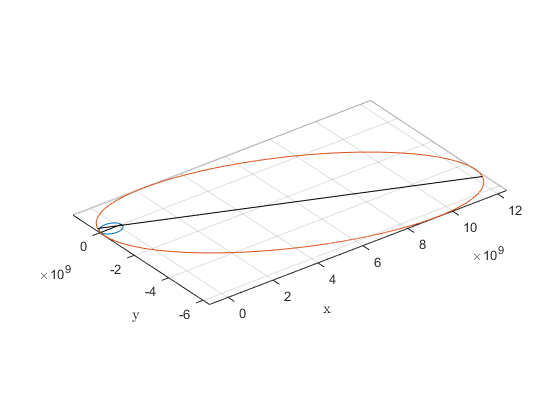

figure
coord_old=plot_orbit_3d(eT,aT,0,0,0);
hold on;
coord_new=plot_orbit_3d(en,an,0,dOmega,0);

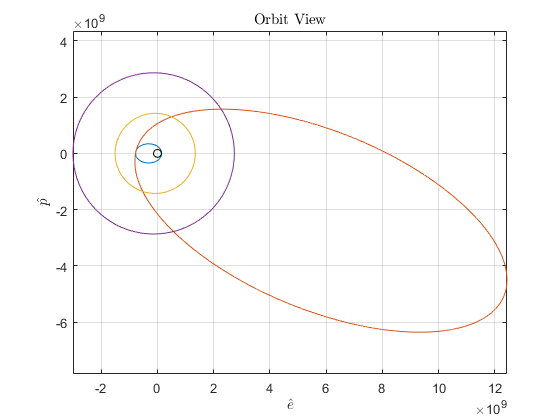


figure
plot(coord_old(1,:),coord_old(2,:))
hold on
plot(coord_new(1,:),coord_new(2,:))
plot_orbit(0.05550825,1427387908);
plot_orbit(0.04685740,2870480873);
axis equal
plot(0,0,'ok')

## Problem 2

R_Earth = 6378.1363;
r1 = R_Earth+190

r1 = 6.5681e+03

aL = 384400;
r2 = aL

r2 = 384400


aT = 0.5*(r1+r2)

aT = 1.9548e+05

eT = 1-r1/aT

eT = 0.9664


ro = r2

ro = 384400

vo = sqrt(2*mu_E/ro-mu_E/aT)

vo = 0.1867

gamma_o = 0

gamma_o = 0

theta_ao = 0

theta_ao = 0


period_o = 2*pi*sqrt(aT^3/mu_E)

period_o = 8.6016e+05

TOF = 0.5*period_o

TOF = 4.3008e+05

epsilon_o = -mu_E/(2*aT)

epsilon_o = -1.0195

period_lun = 2360592;
nL = 2*pi/period_lun

nL = 2.6617e-06

rad2deg(nL)

ans = 1.5250e-04

phi = pi-nL*TOF

phi = 1.9969

rad2deg(phi)

ans = 114.4112

R_Lun = 1738.2;
mu_L = 4902.8005821478;
vL = sqrt(2*mu_E/r2-mu_E/aL)

vL = 1.0183

r_parkL = R_Lun+200

r_parkL = 1.9382e+03

v_inf_L = vL-vo

v_inf_L = 0.8316


ah = mu_L/v_inf_L^2

ah = 7.0887e+03

eh = r_parkL/ah+1

eh = 1.2734

delta = 2*asin(1/eh)

delta = 1.8063

rad2deg(delta)

ans = 103.4943

vn = sqrt(v_inf_L^2+vL^2-2*v_inf_L*vL*cos(delta))

vn = 1.4573

gamma_n = asin(v_inf_L/vn*sin(delta))

gamma_n = 0.5883

rad2deg(gamma_n)

ans = 33.7046


rn = r2

rn = 384400


theta_an = atan2((rn*vn^2/mu_E*sin(gamma_n)*cos(gamma_n)),(rn*vn^2/mu_E*cos(gamma_n)^2-1))

theta_an = 1.1550

rad2deg(theta_an)

ans = 66.1769


en = sqrt((rn*vn^2/mu_E-1)^2*cos(gamma_n)^2+sin(gamma_n)^2)

en = 1.0336

pn = rn*(1+en*cos(theta_an))

pn = 5.4488e+05

an = pn/(1-en^2)

an = -7.9839e+06


rp_n = an*(1-en)

rp_n = 2.6794e+05

ra_n = an*(1+en)

ra_n = -1.6236e+07

period_n = 2*pi*sqrt(an^3/mu_E)

period_n = 0.0000e+00 + 2.2451e+08i

period_n/(3600*24*365)

ans = 0.0000 + 7.1191i

epsilon_n = -mu_E/(2*an)

epsilon_n = 0.0250


dOmega = pi-theta_an

dOmega = 1.9866

rad2deg(dOmega)

ans = 113.8231


dv_eq = sqrt(vo^2+vn^2-2*vo*vn*cos(gamma_n))

dv_eq = 1.3062


beta = pi-asin(vn/dv_eq*sin(gamma_n))

beta = 2.4740

rad2deg(beta)

ans = 141.7471

alpha = pi-beta

alpha = 0.6676

rad2deg(alpha)

ans = 38.2529


dv_vnb = dv_eq*[cos(alpha) 0 sin(alpha)]'

dv_vnb =     1.0257
         0
    0.8087


## Problem 3

aV = 108207284;
mu_V = 324858.59882646;
r1 = aV

r1 = 108207284

r2 = aE

r2 = 149597898


aT = 0.5*(r1+r2)

aT = 128902591

eT = 1-r1/aT

eT = 0.1605


period_o = 2*pi*sqrt(aT^3/mu_S)

period_o = 2.5242e+07

TOF = 0.5*period_o

TOF = 1.2621e+07

epsilon_o = -mu_S/(2*aT)

epsilon_o = -514.7780


nV = sqrt(mu_S/aV^3)

nV = 3.2365e-07

rad2deg(nV)

ans = 1.8544e-05

phi = pi-nV*TOF

phi = -0.9431

rad2deg(phi)

ans = -54.0347

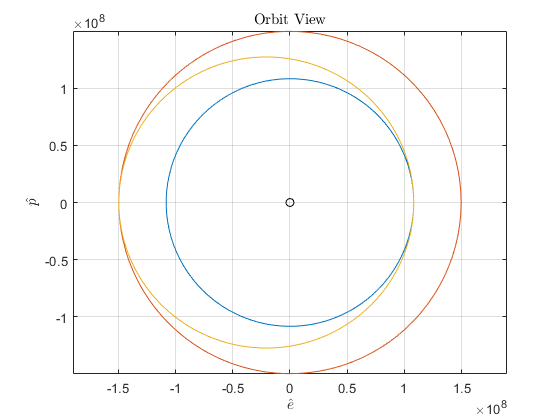

figure
plot_orbit(0,aV);
hold on
plot_orbit(0,aE);
plot_orbit(eT,aT);

ro = r2;
vE = sqrt(2*mu_S/r2-mu_S/aE)

vE = 29.7847

va = sqrt(2*mu_S/r2-mu_S/aT)

va = 27.2892

v_inf_E = vE-va

v_inf_E = 2.4955


r_parkE = R_Earth+210

r_parkE = 6.5881e+03

vc_E = sqrt(mu_E/r_parkE)

vc_E = 7.7784

dv_E = sqrt(v_inf_E^2+2*mu_E/r_parkE) - vc_E

dv_E = 3.5014

rpo = r1

rpo = 108207284

rao = r2

rao = 149597898

epsilon_o = -mu_S/(2*aT)

epsilon_o = -514.7780

ro = rpo

ro = 108207284

vo = sqrt(2*mu_S/ro-mu_S/aT)

vo = 37.7276

gamma_o = 0

gamma_o = 0

theta_ao = 0

theta_ao = 0

R_Venus = 6051.9;
r_parkV = R_Venus+2000

r_parkV = 8.0519e+03

vc = sqrt(mu_V/r_parkV)

vc = 6.3518

vV = sqrt(mu_S/aV)

vV = 35.0209

v_inf_V = vo-vV

v_inf_V = 2.7067

dv_V = sqrt(v_inf_V^2+2*mu_V/r_parkV)-vc

dv_V = 3.0299


dv_total = dv_E+dv_V

dv_total = 6.5314

ah = mu_V/v_inf_V^2

ah = 4.4342e+04

eh = r_parkV/ah+1

eh = 1.1816

delta = 2*asin(1/eh)

delta = 2.0181

rad2deg(delta)

ans = 115.6271

vn = sqrt(v_inf_V^2+vV^2-2*v_inf_V*vV*cos(delta))

vn = 36.2738

gamma_n = -asin(v_inf_V/vn*sin(delta))

gamma_n = -0.0673

rad2deg(gamma_n)

ans = -3.8577


rn = ro

rn = 108207284


theta_an = atan2((rn*vn^2/mu_S*sin(gamma_n)*cos(gamma_n)),(rn*vn^2/mu_S*cos(gamma_n)^2-1))

theta_an = -0.8143

rad2deg(theta_an)

ans = -46.6535


en = sqrt((rn*vn^2/mu_S-1)^2*cos(gamma_n)^2+sin(gamma_n)^2)

en = 0.0990

pn = rn*(1+en*cos(theta_an))

pn = 1.1556e+08

an = pn/(1-en^2)

an = 1.1671e+08


rp_n = an*(1-en)

rp_n = 1.0515e+08

ra_n = an*(1+en)

ra_n = 1.2826e+08

period_n = 2*pi*sqrt(an^3/mu_S)

period_n = 2.1746e+07

period_n/(3600*24*365)

ans = 0.6895

epsilon_n = -mu_S/(2*an)

epsilon_n = -568.5710


dOmega = 0-theta_an

dOmega = 0.8143

rad2deg(dOmega)

ans = 46.6535


dv_eq = sqrt(vo^2+vn^2-2*vo*vn*cos(gamma_n))

dv_eq = 2.8836


beta = asin(vn/dv_eq*sin(gamma_n))

beta = -1.0090

rad2deg(beta)

ans = -57.8135

alpha = pi-beta

alpha = 4.1506

rad2deg(alpha)

ans = 237.8135


dv_vnb = dv_eq*[cos(alpha) 0 sin(alpha)]'

dv_vnb =    -1.5360
         0
   -2.4404


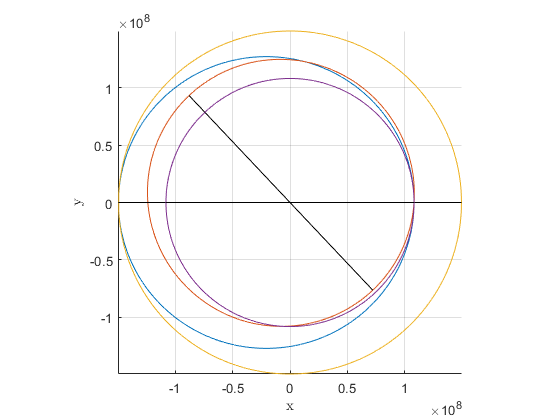

figure
plot_orbit_3d(eT,aT,0,0,0);
hold on;
plot_orbit_3d(en,an,0,dOmega,0);
plot_orbit_3d(0,aE,0,0,0);
plot_orbit_3d(0,aV,0,0,0);
axis equal
view([0,0,1])

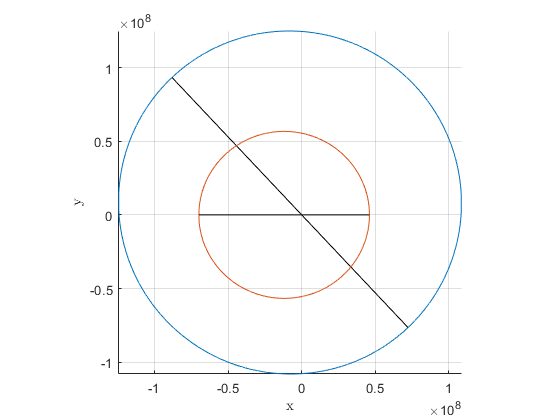

figure
plot_orbit_3d(en,an,0,dOmega,0);
hold on;
plot_orbit_3d(0.20563661,57909101,0,0,0);
view([0 0 1])